clc; close all; clear all;

y_1_name = "y1.wav";
y_2_name = "y2.wav";
s_1_name = "Doimo_Ostan_s1_hat.wav"

s_1_name = "Doimo_Ostan_s1_hat.wav"

s_2_name = "Doimo_Ostan_s2_hat.wav"

s_2_name = "Doimo_Ostan_s2_hat.wav"

s_3_name = "Doimo_Ostan_s3_hat.wav"

s_3_name = "Doimo_Ostan_s3_hat.wav"


if not(isfolder("audioOutputs"))
    mkdir("audioOutputs")
end

addpath('audioInputs')
addpath('audioOutputs')

[y_1_t,y_1_Fs] = audioread(y_1_name);
[y_2_t,y_2_Fs] = audioread(y_2_name);
y_1_t_len = length(y_1_t);
y_2_t_len = length(y_2_t);

M=1024

M = 1024

R=M/2

R = 512

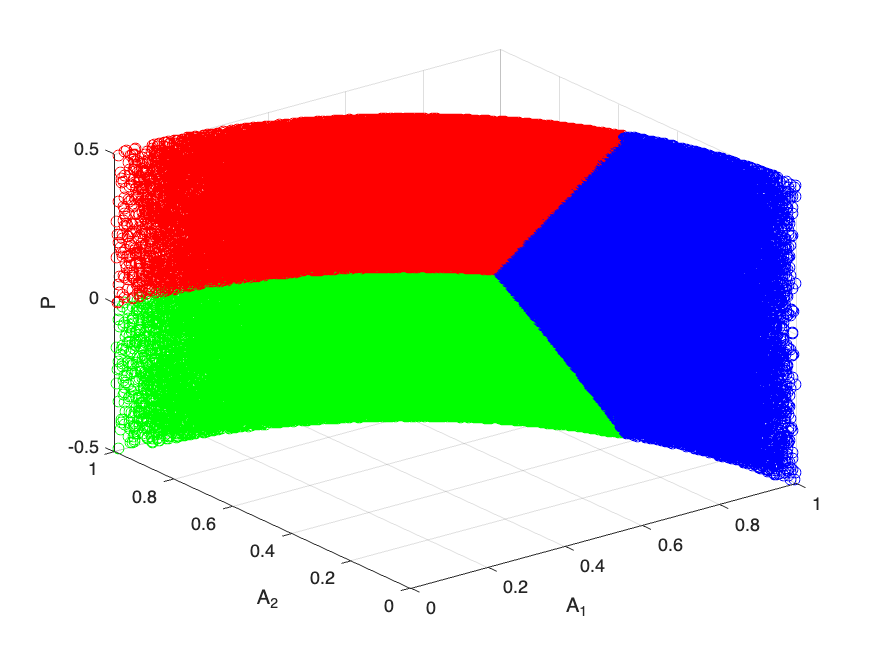


y_1_st_w = mystft(y_1_t,"hann",M,R);
y_2_st_w = mystft(y_2_t,"hann",M,R);

y_1_w_lin = reshape(y_1_st_w,size(y_1_st_w,1)*size(y_1_st_w,2),1);
y_2_w_lin = reshape(y_2_st_w,size(y_2_st_w,1)*size(y_2_st_w,2),1);

if(length(y_2_w_lin) ~= length(y_1_w_lin))
    disp("error between microphones signal length")
end
FI = zeros(length(y_1_w_lin),3);

% compute first and feature
for ii = 1:length(y_1_w_lin)
   Y_1 = y_1_w_lin(ii);
   Y_2 = y_2_w_lin(ii);
   root_sum = (sqrt(abs(Y_1)^2 + abs(Y_2)^2));
   A_1 = abs(Y_1) / root_sum;
   A_2 = abs(Y_2) / root_sum;
   P = 1/(2*pi) * angle(Y_2/Y_1);
   FI(ii,1) = A_1;
   FI(ii,2) = A_2;
   FI(ii,3) = P;
end

idx = kmeans(FI,3);
figure
scatter3(FI(idx==1,1),FI(idx==1,2),FI(idx==1,3),'ro')
hold on
scatter3(FI(idx==2,1),FI(idx==2,2),FI(idx==2,3),'bo')
hold on
scatter3(FI(idx==3,1),FI(idx==3,2),FI(idx==3,3),'go')
xlabel("A_1")
ylabel("A_2")
zlabel("P")

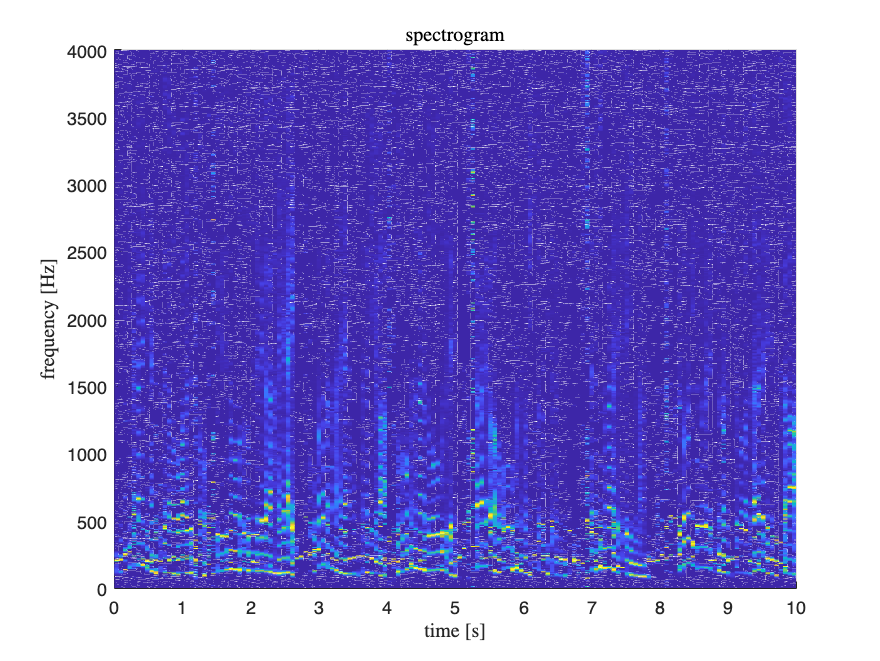

M_1_lin = zeros(length(idx),1);
M_2_lin = zeros(length(idx),1);
M_3_lin = zeros(length(idx),1);
for ii = 1: length(idx)
    if idx(ii) == 1
        M_1_lin(ii) = 1;
    elseif idx(ii) == 2
        M_2_lin(ii) = 1;
    elseif idx(ii) == 3
        M_3_lin(ii) = 1;
    end
end

%M_1 = reshape(M_1_lin,size(y_1_st_w,1),size(y_1_st_w,2));
%M_2 = reshape(M_2_lin,size(y_1_st_w,1),size(y_1_st_w,2));
%M_3 = reshape(M_3_lin,size(y_1_st_w,1),size(y_1_st_w,2));

S_1_lin = y_1_w_lin .* M_1_lin;
S_2_lin = y_1_w_lin .* M_2_lin;
S_3_lin = y_1_w_lin .* M_3_lin;

S_1 = reshape(S_1_lin,size(y_1_st_w,1),size(y_1_st_w,2));
S_2 = reshape(S_2_lin,size(y_1_st_w,1),size(y_1_st_w,2));
S_3 = reshape(S_3_lin,size(y_1_st_w,1),size(y_1_st_w,2));

figure 
w1 = linspace(0,y_1_Fs/2,M/2);
t =linspace(0,y_1_t_len/y_1_Fs,size(y_1_st_w,2));
S_11 = S_1(1:M/2,:);
surf(t,w1,abs(S_11)./(max(abs(S_11))),EdgeColor="none");
%ylim([0 2000])
view(0,90);
xlabel("time [s]",Interpreter="latex");
ylabel("frequency [Hz]",Interpreter="latex");
title('spectrogram',Interpreter='Latex');

%for nn = 1:size(S_1,2)
%    S_1(M+1:2*M+1,nn) = 0;
%    S_2(M+1:2*M+1,nn) = 0;
%    S_3(M+1:2*M+1,nn) = 0;
%end

s_1_t = myistft(S_1,M,R);

Nframes = 156

s_2_t = myistft(S_2,M,R);

Nframes = 156

s_3_t = myistft(S_3,M,R);

Nframes = 156


audiowrite("./audioOutputs/"+s_1_name,real(s_1_t)/max(real(s_1_t)),y_1_Fs);

audiowrite("./audioOutputs/"+s_2_name,real(s_2_t)/max(real(s_2_t)),y_1_Fs);
audiowrite("./audioOutputs/"+s_3_name,real(s_3_t)/max(real(s_3_t)),y_1_Fs);